# MATH-340 Final Exam 

## Amelia Rotondo - CWID: 887925113

## --- Part A: ---

### Problem A1: 

Floating-Point Error on the Marc-5

% EPS Demo
t = 0.1;
n = 1:10;
e = n/10 - n*t;

% Display for Considering Error 
disp(e);

   1.0e-15 *

         0         0   -0.0555         0         0   -0.1110   -0.1110         0         0         0



disp(e/eps);

         0         0   -0.2500         0         0   -0.5000   -0.5000         0         0         0



    Entering the following commands on the Marc-5 would lead to some nonzero negative values in the e-vector. This is because the representation of decimal multiples is just slightly greater than the representation of fractional calculation for certain values. Since the Marc-5 uses 5 bits for the fraction, it truncates 0.1 (0.000110011...) as 5 bits, resulting in the binary representation of `0.00011`. This binary representation, when multiplied by numbers such as 3 (11 in binary) results in the value `0.01001` (or the normalized 1.00110 * 2^-2). Since fractions can be easily chopped based on the precision of the division operator. **Therefore, while for some values the truncation of the decimal point produces no difference in result, ultimately some results such as `3/10 - 3*0.1` produce noticable differences in decimal truncation that lead to inaccurate answers. **

### Problem A2: 


$$\text{consider: } x-9^{-x} = 0$$


#### Part A2-A: 

% Define the function
f = @(x) x-9.^(-x);

% Evaluate x = 0
x = 0; 
y = f(x);
fprintf('At x = %.3f, y = %.3f', x, y)

At x = 0.000, y = -1.000


% Evaluate x = 1
x = 1; 
y = f(x);
fprintf('At x = %.3f, y = %.3f', x, y)

At x = 1.000, y = 0.889


% Check if there is a Sign Change
if f(0) * f(1) < 0
    disp('There is a root in the interval (0,1)');
else
    disp('No root found in the interval (0,1)');
end

There is a root in the interval (0,1)


#### Part A2-B: 

% Define the points
x = [0, 0.5, 1];
y = f(x);

% Find Interpolating Polynomail
p = polyfit(x, y, 2);
fprintf('\nPolynomial: (%.4f)x^2 + (%.4f)x + (%.4f)\n', p);


Polynomial: (-0.8889)x^2 + (2.7778)x + (-1.0000)



% Find Polynomial Root
root_p = fzero(f, [0, 1]);
fprintf('\nroot for y = x - 9^(-x) is: %.6f\n', root_p)


root for y = x - 9^(-x) is: 0.408004


#### Part A2-C: 

% Initial Values
x0 = 0;
x1 = 0.5;

% One Secant Method Iteration
s2 = (x1-x0)/(f(x1)-f(x0));
x2 = x1 - f(x1) * s2;
fprintf('\nx2 = %.6f\n', x2);


x2 = 0.428571



% Compare with Exact Zero
exact_zero = 0.408004;
error = abs(x2 - exact_zero);
fprintf('\nError for 1 Step: %.6f\n', error);


Error for 1 Step: 0.020567


### Problem A3: 


$$p(x) = (x-1)^2(x-2)^2(x-3)\\
p(1) = p(2)=p(3) = 0\\
a_0 < 1, b_0 > 3, \rightarrow  f(a_0)f(b_0)< 0\\
\text{if:}\\
c_n = (a_n+b_n)/2 \neq 1, 2, \text{or } 3,  [ \forall n \geq1]\\$$


% Define Starting Values
p = @(x) (x - 1).^2 .* (x - 2).^2 .* (x - 3);
c = @(a, b) (a+b)/2;
a0 = 0.1; % less than 1
b0 = 3.5; % greater than 3 

% Check c_n for initial values (neq 1, 2, or 3)
c0 = c(a0, b0);
fprintf('\nc0 = %.5f (which is not 1, 2, or 3)\n', c0);


c0 = 1.80000 (which is not 1, 2, or 3)



% Bisection Method 
zero = myBisection(p, a0, b0);


a: 0.100, c: 1.800, b: 3.500
a: 1.800, c: 2.650, b: 3.500
a: 2.650, c: 3.075, b: 3.500
a: 2.650, c: 2.862, b: 3.075
a: 2.862, c: 2.969, b: 3.075
a: 2.969, c: 3.022, b: 3.075
a: 2.969, c: 2.995, b: 3.022
a: 2.995, c: 3.009, b: 3.022
a: 2.995, c: 3.002, b: 3.009

fprintf('\nBisection Converges to %.1f\n', zero);


Bisection Converges to 3.0


    The bisection method uses the change in sign over a given midpoint to find a zero within a given function. Since f(a)f(b) < 0, the function will always start by iteratively moving the guess of the lower-bound. To the midpoint. Furthermore, since the function is either negative or zero from the domain 0 to 3, this process will continue until f(c) > b. **Therefore, this iterative process will always converge to the zero of 3 so long as the midpoint (c_n) never equals 1 or 2. **

### Problem A4:

% Given Values
corners = [1, 0; 0, 1; -1, 0; 0, -1];
z = [0; 1; 3; 4];

% Set up A to best-fit z (for Ax = z)
A = [ones(size(corners, 1), 1), corners];

% Solve for Coefficients
coefficients = A \ z;

% Extract coefficients C, D, E
C = coefficients(1);
D = coefficients(2);
E = coefficients(3);


% Calculate the average of the z values
z_avg = mean(z);

% Calculate the Center of the Square
z_center = C + D*0 + E*0;

% Display the Needed Results
disp('The Values of Matrix A:');

The Values of Matrix A:


disp(A);

     1     1     0
     1     0     1
     1    -1     0
     1     0    -1



fprintf('Coefficients (C, D, E): (%.2f, %.2f, %.2f)\n', C, D, E);

Coefficients (C, D, E): (2.00, -1.50, -1.50)


fprintf('Center of the Square  : C + Dx + Ey = %.2f\n', z_center);

Center of the Square  : C + Dx + Ey = 2.00


fprintf('Average of z-values   : %.2f\n', z_avg);

Average of z-values   : 2.00


    **As shown in this output, it's clear that the average of the z-values is also equal to the center of the square. **

## --- Part B: --- 

### Problem B1:

% Data
y = [2009, 2010, 2011, 2012, 2013, 2014, 2015, 2016, 2017, 2018, 2019, 2020];
v = [5.26, 4.87, 4.56, 3.57, 5.21, 5.22, 4.62, 4.53, 4.82, 4.79, 4.36, 3.92];

% Set-up Plot 
figure(1); clf; hold on;
title('Amelia Rotondo: Problem B1 Graph')
legend('Location','best');
plot(y, v, 'b*', 'DisplayName', 'Original Data');

#### Part B1-A: 

% Linear least squares fitting
p1 = polyfit(y, v, 1);

% Display the coefficients
fprintf('\nLeast Squares Solution: v = (%.6f)y + (%.6f)\n', p1);


Least Squares Solution: v = (-0.049336)y + (104.030862)


#### Part B1-B:

% Modified Data (2012 Removed)
y_mod = [2009, 2010, 2011, 2013, 2014, 2015, 2016, 2017, 2018, 2019, 2020];
v_mod = [5.26, 4.87, 4.56, 5.21, 5.22, 4.62, 4.53, 4.82, 4.79, 4.36, 3.92];

% Modified Least Squares
p1_mod = polyfit(y_mod, v_mod, 1);

% Display the coefficients
fprintf('\nLeast Squares Solution: v = (%.6f)y + (%.6f)\n', p1_mod);


Least Squares Solution: v = (-0.073318)y + (152.457103)


#### Part B1-C:

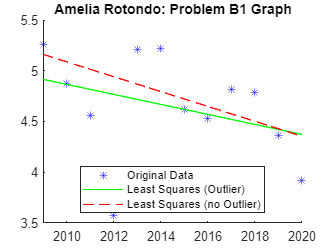

% Plot Results 
v1 = polyval(p1, y);
v1_mod = polyval(p1_mod, y_mod);
plot(y, v1, 'g-', 'DisplayName', 'Least Squares (Outlier)');
plot(y_mod, v1_mod, 'r--', 'DisplayName', 'Least Squares (no Outlier)');

#### Part B1-D: 

% Find the Zeroes for the Two Models 
root_p1 = ceil(roots(p1));
root_p1_mod = ceil(roots(p1_mod));

% Display Results 
fprintf('\nI Estimate that All The Ice Melts In Year:\nWith Outlier   : %i\nWithout Outlier: %i\n', root_p1, root_p1_mod);


I Estimate that All The Ice Melts In Year:
With Outlier   : 2109
Without Outlier: 2080


### Problem B2:

Lotka-Volterra Predator-Prey Model 

% Given Values
alpha = 0.01; beta = 0.01;
r = 2; k = 1; 
x0 = 300; y0 = 150; 
tmax = 50; 

#### Part B2-A:

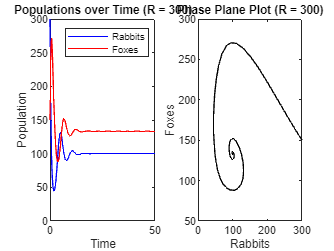

% Constants
R = 300;

% ODE Solution
[t, y] = lotkaVolterraModel(r, R, alpha, beta, k, x0, y0, tmax);

% Plotting
figure;
subplot(1,2,1);
plot(t, y(:,1), 'b', t, y(:,2), 'r');
title('Populations over Time (R = 300)');
xlabel('Time');
ylabel('Population');
legend('Rabbits', 'Foxes');

subplot(1,2,2);
plot(y(:,1), y(:,2), 'k');
title('Phase Plane Plot (R = 300)');
xlabel('Rabbits');
ylabel('Foxes');

#### Part B2-B: 

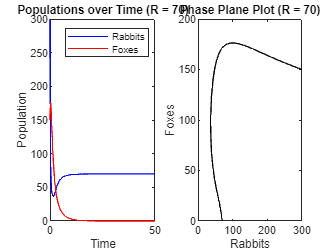

% Constants
R = 70;

% ODE Solution
[t, y] = lotkaVolterraModel(r, R, alpha, beta, k, x0, y0, tmax);

% Plotting
figure;
subplot(1,2,1);
plot(t, y(:,1), 'b', t, y(:,2), 'r');
title('Populations over Time (R = 70)');
xlabel('Time');
ylabel('Population');
legend('Rabbits', 'Foxes');

subplot(1,2,2);
plot(y(:,1), y(:,2), 'k');
title('Phase Plane Plot (R = 70)');
xlabel('Rabbits');
ylabel('Foxes');

#### Find the Minimal R Value: 

% Choose a Reasonably-Long Timespan
tmax = 400; 

% Initialize R
R = 10; 

% Initialize Variables
increment = 1; 
found = false;

while ~found
    % Solve the ODEs with the current R
    [t, y] = lotkaVolterraModel(r, R, alpha, beta, k, x0, y0, tmax);
    
    % Check if the predator population ever goes below 2
    if all(y(:, 2) >= 2)
        found = true;
        break;
    else
        R = R + increment; % Increase R
    end
end

% Display the minimal R
fprintf('Minimal Carrying Capacity R: %d\n', R);

Minimal Carrying Capacity R: 101


    For my analysis of the Minimal Carrying Capacity, I iteratively searched until I determined the scenario where the population of the wolves never drops below 2; since wolves cannot reproduce unless there are two of them alive. **Therefore, I've concluded that the minimal carrying capacity (R) that allows the predators to survive is 101. **

### Problem B3:

Interplanetary Bob Beamon 

% Given Values 
m = 80;       
c = 0.72;     
s = 0.50;    
theta0 = pi/8; 
dist = 8.90;  

#### Part B3-A:

% Earth Constants
g = 9.81; 
rho = 0.94;    

% Solving for the initial velocity
Tmax = 100;
v0 = fzero(@(v0) jumpDistDiff(v0, g, m, c, rho, s, theta0, Tmax, dist), 10);

% Display the result
fprintf('Initial velocity for the jump on Earth: %.4f m/s\n', v0);

Initial velocity for the jump on Earth: 11.1847 m/s


#### Part B3-B: 

% Moon Constants
g_moon = 1.62519; 
rho_moon = 0;     

% ODE Solution for the Moon
rhs_moon = @(t, y) longJumpODE(t, y, g_moon, m, c, rho_moon, s);
opts_moon = odeset('Events', @reachesGround);
[~, ~, ~, ye_moon, ~] = ode45(rhs_moon, [0, Tmax], [0, 0, theta0, v0], opts_moon);
moon_jump_dist = ye_moon(:, 1);

% Display the result
fprintf('Jump distance on the Moon: %.4f m\n', moon_jump_dist);

Jump distance on the Moon: 54.4252 m


#### Part B3-C: 

% Venus Constants
g_venus = 8.87;  
rho_venus = 65;  

% Solving for the takeoff velocity on Venus
v0_venus = fzero(@(v0) jumpDistDiff(v0, g_venus, m, c, rho_venus, s, theta0, Tmax, dist), 10);

% Display the result
fprintf('Takeoff velocity on Venus to beat 8.90 m: %.4f m/s\n', v0_venus);

Takeoff velocity on Venus to beat 8.90 m: 18.5861 m/s


fprintf('Differences Between Earth and Venus:\nVelocity   :  %.4f\nGravity    :  %.4f\nAir Density: %.4f\n', abs(v0 - v0_venus), abs(g - g_venus), abs(rho - rho_venus));

Differences Between Earth and Venus:
Velocity   :  7.4015
Gravity    :  0.9400
Air Density: 64.0600


    Given the shown differences between the 8.9m long-jump on Earth and Venus, it's clear that the greatest difference is in the air-density of the two planets. **Therefore, it's fair to assume that in this interplanetary circumstance- the factor most important for distance traveled is air density. **

### Problem B4:

% I'm tired and don't want to do a closed 3-body orbit ODE 
% Your class has been one of my favorites at this university 
% Despite how much work I could or couldn't complete, 
% I thoroughly enjoyed getting to learn about Numerical Analysis. 
% Thank you for your help, and have a nice winter break professor! 

## --- ETC: FUNCTIONS ---

myBisection:

function zero = myBisection(fun, a0, b0)

    % Set the tolerance
    tol = 1e-2;

    % Initialize variables
    a = a0;
    b = b0;
    fa = fun(a);
    fb = fun(b);

    % Bisection loop
    while (b - a) > tol
        c = (a + b) / 2; % Midpoint
        fc = fun(c);

        % Debugging
        fprintf('\na: %.3f, c: %.3f, b: %.3f', a, c, b);

        if fa * fc < 0
            b = c;
            fb = fc;
        else
            a = c;
            fa = fc;
        end
    end

    % Final approximation of the zero
    zero = (a + b) / 2;
end

LongJumpODE: 

function dydt = longJumpODE(t, y, g, m, c, rho, s)
    % Extract State Variables 
    x = y(1);       % Horizontal position 
    y_pos = y(2);   % Vertical position
    theta = y(3);   % Angle of the jumper's velocity vector
    v = y(4);       % Magnitude of the jumper's velocity

    % Calculate the drag force
    D = (c * rho * s * v^2) / 2;

    % Compute the derivatives (RHS of the ODE system)
    dxdt = v * cos(theta);                       
    dydt = v * sin(theta);                       
    dthetadt = -g * cos(theta) / v;            
    dvdt = -(D/m) - g * sin(theta);  

    % Assemble the Vector of Derivatives
    dydt = [dxdt; dydt; dthetadt; dvdt];
end

% Event to Check for the Jump Reaching the Ground
function [value, isterminal, direction] = reachesGround(t, y)
    value = y(2);       % Check the height of the jumper, which is y(2)
    isterminal = 1;     % Stop the solver when the height crosses zero
    direction = -1;     % Detect when the height is decreasing through zero
end

% Finds Difference between Desired Distance and Distance Achieved for v0 
function distDifference = jumpDistDiff(v0, g, m, c, rho, s, theta0, Tmax, dist)

    % Solve the ODE for the v0 guess
    rhs = @(t, y) longJumpODE(t, y, g, m, c, rho, s);
    opts = odeset('Events', @reachesGround);
    [t, y, te, ye, ie] = ode45(rhs, [0, Tmax], [0, 0, theta0, v0], opts);
    
    % Determine Jump Distance Difference
    jump_distance = ye(end, 1); 
    distDifference = jump_distance - dist;
end

lotkaVolterraModel: 

function [t, y] = lotkaVolterraModel(r, R, alpha, beta, k, x0, y0, tmax)
    
    % ODE Solution
    tspan = [0, tmax];
    dydt = @(t, y) [r * y(1) * (1 - y(1) / R) - alpha * y(1) * y(2); 
                    -k * y(2) + beta * y(1) * y(2)];
    [t, y] = ode45(dydt, tspan, [x0, y0]);

end